BME3053C Computer Applications Project

Group Members: Gionela Lepage, Trey Chesser, Fabiana Amato

Course: BME 3053C Computer Applications for BME

Term: Fall 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Step 1: Read the audio file and plot it in the time domain

[y, Fs] = audioread("214_1b1_Ar_sc_Meditron.wav");
%sound(y,Fs);
L=length(y);
N=size(y,1);
T=1/Fs;
t = (0:L-1)*T

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


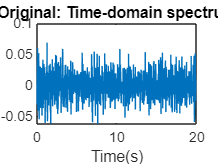

plot(t,y); 
title('Original: Time-domain spectrum'); xlabel('Time(s)');

Step 2: Convert the file into the frequency domain and plot it

%bandpass filter
y2=bandpass(y,[20 200],Fs)

y2 =     0.0092
    0.0092
    0.0092
    0.0092
    0.0093
    0.0093
    0.0093
    0.0093
    0.0093
    0.0093


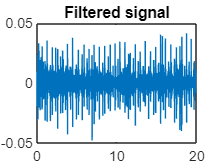

figure(1)
plot(t,y2)
title('Filtered signal')


% %Sgolay filter (not worth it)
% y3=sgolayfilt(y2,100,101)
% figure(2)
% plot(t,y3)
% title('SGolay filtered signal')

%FFT
df=Fs/N

df = 0.0504

w=(-(N/2):(N/2)-1)*df

w = 	1.0e+04 *

   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048


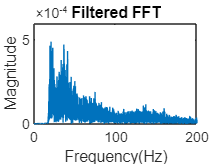

Y=fft(y2)/N;
Y=fftshift(Y);
figure; plot(w,abs(Y))
title('Filtered FFT');xlabel('Frequency(Hz)')
ylabel('Magnitude')
xlim([0 200])


%periodogram
[P1,f1]=periodogram(y2,[],[],Fs,'Power')

P1 = 	1.0e+-6 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


f1 = 	1.0e+04 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


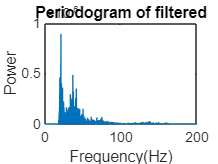

figure(3)
plot(f1,P1)
xlim([0 200])
title('Periodogram of filtered')
xlabel('Frequency(Hz)')
ylabel('Power')

Step 3: Filtering 

% % plotting power spectrum before filtering
% [P1,f1]=periodogram(y,[],[],Fs,'Power')
% figure(1)
% plot(f1,P1)
% xlim([0 200])
% title('Periodogram of unfiltered')
% 
% % applying bandpass filter from 20-2000 Hz
% y3=bandpass(y2,[20 200],Fs)
% y4=fftshift(y3)
% figure(2)
% plot(w,abs(y4))
% title('Filtered signal')
% 
% %inverse FT of filtered signal
% x=ifft(y3);
% 
% %periodogram of filtered signal
% [P2,f2]=periodogram(x,[],[],Fs,'Power')
% figure(3)
% plot(f2,P2)
% xlim([0 200])
% title('Periodogram of filtered')
F=abs(Y)

F = 	1.0e+-3 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


g=mean(F);

if g>3e-6
    fprintf('The patient has COPD')
else
    fprintf('The patient is healthy')
end

The patient is healthy